clear

syms s;

a = 2.66;
T = .188;
kc = 1.7;

c = kc*tf([a*T,1],[T,1])

c =
 
  0.8501 s + 1.7
  --------------
   0.188 s + 1
 
Continuous-time transfer function.




expand(s*(s+2)*(s+10)); %the denominator of P(s)

p = tf([0,20],[1,12,20,0])

p =
 
          20
  -------------------
  s^3 + 12 s^2 + 20 s
 
Continuous-time transfer function.



G = c*p

G =
 
                 17 s + 34
  ----------------------------------------
  0.188 s^4 + 3.256 s^3 + 15.76 s^2 + 20 s
 
Continuous-time transfer function.




M = feedback(G,1)

M =
 
                    17 s + 34
  ---------------------------------------------
  0.188 s^4 + 3.256 s^3 + 15.76 s^2 + 37 s + 34
 
Continuous-time transfer function.



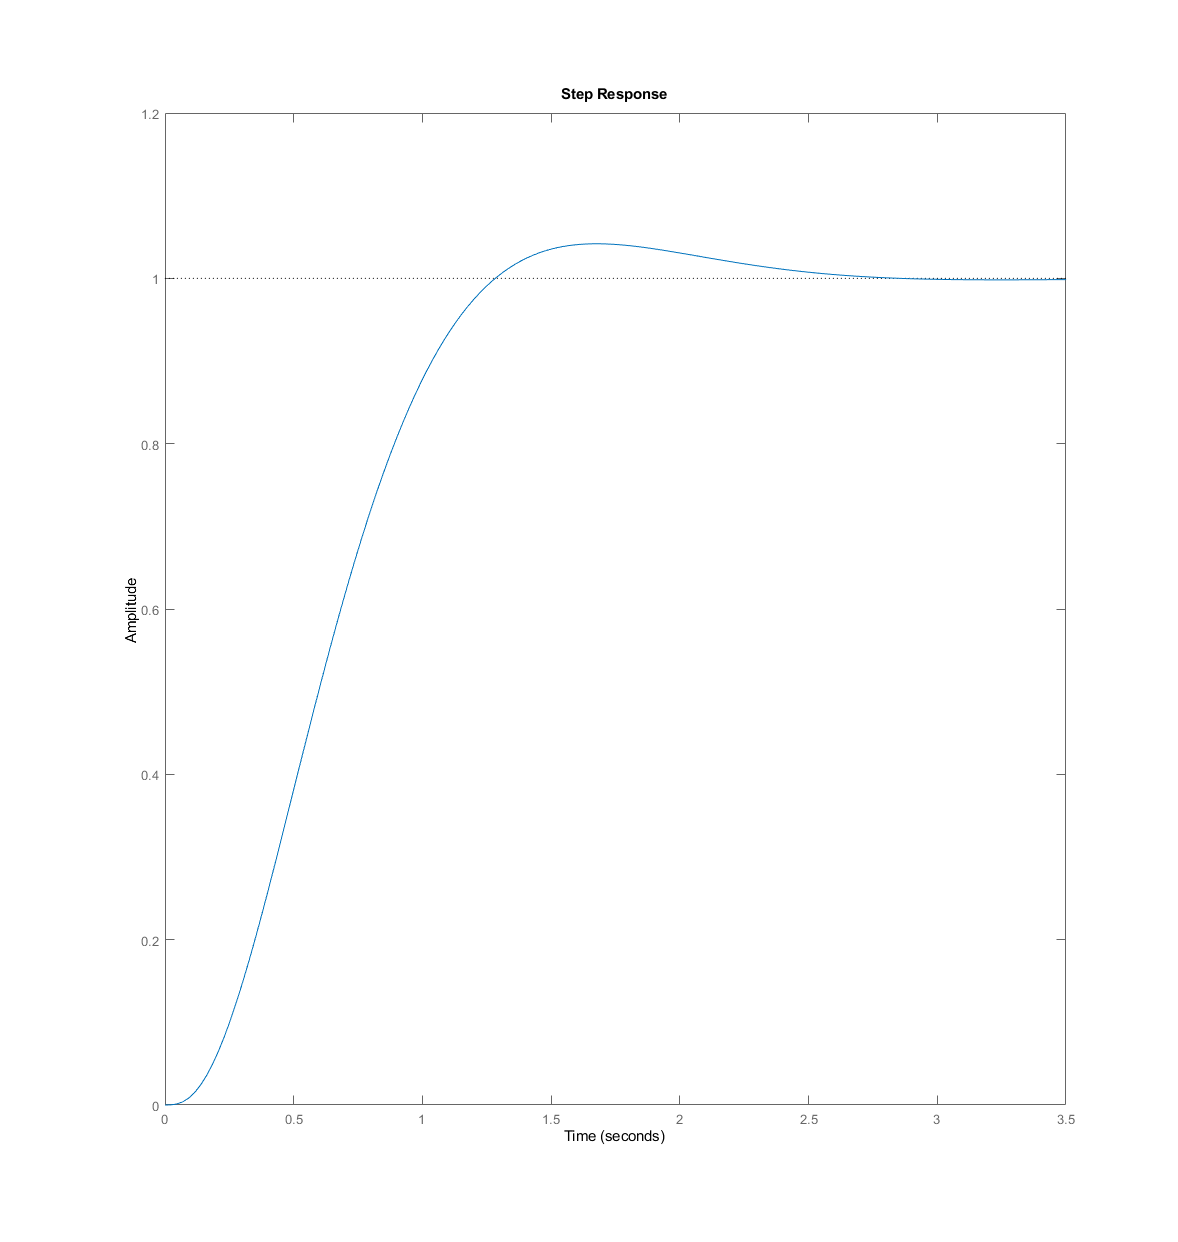


step(M)